# Attacking Subsystem- Performance Evaluation for spoofing target accuracy

## Initialize the Evaluation Script

clear;
c = clock;
seed = floor(sum(c));
rng(seed);
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
%  file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "1GHz.json";
file_path = "4GHz.json";

config_path = david_path + file_path;

### Generate Test Ranges and Velocities

valid_ranges = [50,100];
valid_velocities = [-25,25];
num_cases = 100;
frames_to_compute = 11;
attack_start_frame = 7;
save_file_name = "attack_subsystem_spoofing_performance";

% [spoof_ranges,spoof_velocities] = characterization_functions.initialize_attack_subsystem_test_cases(num_cases, ...
%                 valid_ranges, ...
%                 valid_velocities);
% 
% test_data_spoofing_performance = ...
%                 characterization_functions.run_spoofing_performance_test_cases(num_cases, ...
%                     frames_to_compute, ...
%                     attack_start_frame, ...
%                     spoof_ranges, ...
%                     spoof_velocities, ...
%                     config_path, ...
%                     save_file_name);

### Plot Test Case Information

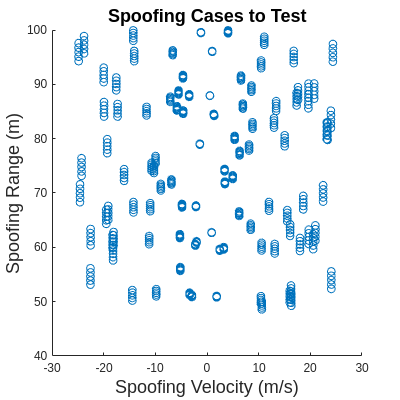

read_file_name = save_file_name + ".csv";
characterization_functions.plot_spoofing_test_configurations(read_file_name);

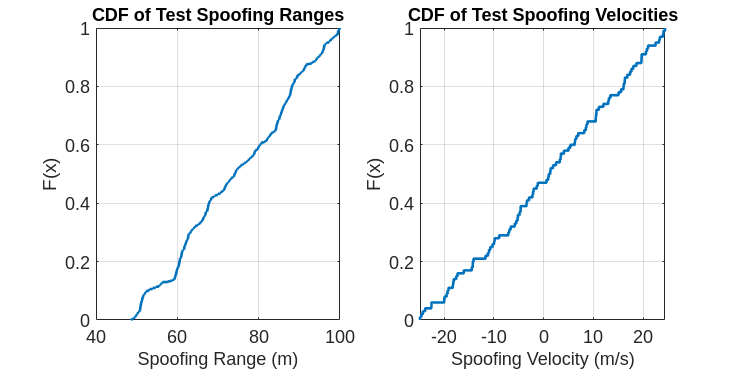

characterization_functions.plot_spoofing_test_configuration_cdfs(read_file_name);

### Plot Test Case Results

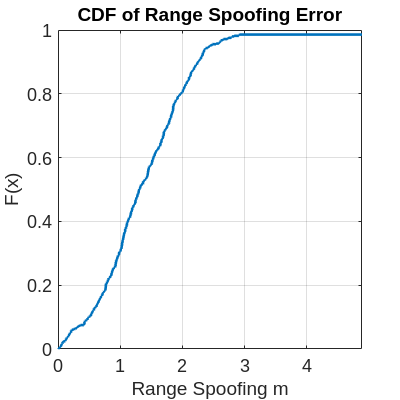

ans = 1×5 table
    Mean (m)    Variance (m)^2    MSE (m)^2    95th Percentile (m)    Percent Failed Trials
    ________    ______________    _________    ___________________    _____________________

     2.8235         175.36         182.97            2.4429                   0.012        


% plot Range Spoofing Error
actual_values_idx = 1;
estimated_values_idx = 3;
abs_errors_idx = 5;
metric_title = "Range Spoofing";
metric_units = "m";
percentile = 95;
scale_factor = 1;
characterization_functions.generate_testing_summary(read_file_name,...
    actual_values_idx, ...
    estimated_values_idx, ...
    abs_errors_idx, ...
    metric_title, ...
    metric_units,...
    percentile,...
    scale_factor)

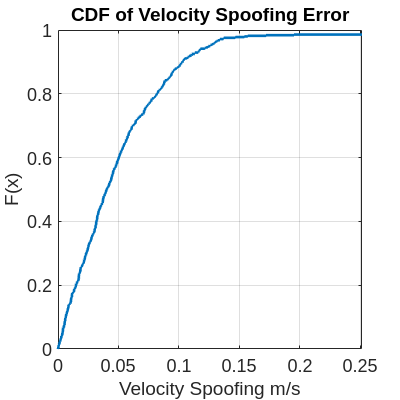

ans = 1×5 table
    Mean (m/s)    Variance (m/s)^2    MSE (m/s)^2    95th Percentile (m/s)    Percent Failed Trials
    __________    ________________    ___________    _____________________    _____________________

     0.35898           10.174           10.282              0.12567                   0.012        


%Summary of Spoofing Velocity Performance
actual_values_idx = 2;
estimated_values_idx = 4;
abs_errors_idx = 6;
metric_title = "Velocity Spoofing";
metric_units = "m/s";
percentile = 95;
scale_factor = 1;
characterization_functions.generate_testing_summary(read_file_name,...
    actual_values_idx, ...
    estimated_values_idx, ...
    abs_errors_idx, ...
    metric_title, ...
    metric_units,...
    percentile,...
    scale_factor)